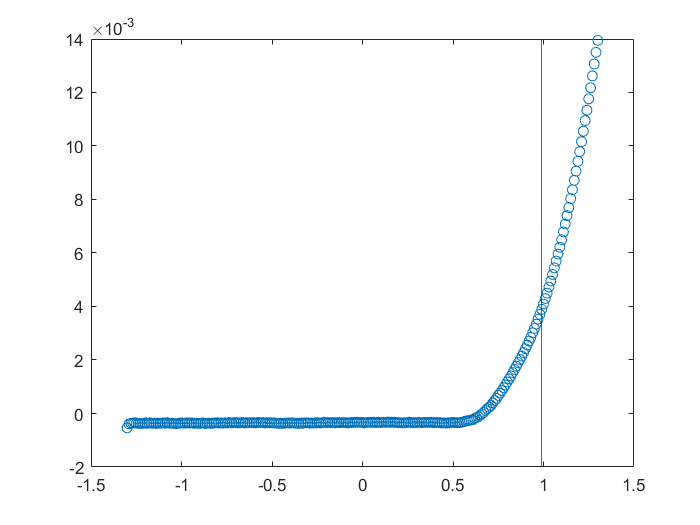

clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

TEMPERATURE = 295; % K
V_T = 0.02585*TEMPERATURE/300; % Thermal voltage in V

% Import
LPath = 'D:\Profile\qse\Files\_PVcomB SHJ fabrication\_run1\2022-11-09 IV curve\Cell13_jD.txt';

ivdata = importdata(LPath, '\t', 21);
V = ivdata.data(:,1);
I = (ivdata.data(:,2) + ivdata.data(:,3))/2; % mA
I = I/1000; % A
nI = numel(I);

figure()
plot(V, I, 'o')
xline(V(230)) %idxStartStart

# Fit in the forward bias region

## Caluclate the x y pairs

nStart = 10;
IDX_START_IN = 220;
IDX_START_FIN = IDX_START_IN + nStart - 1;
[alpha1, alpha1Std, alpha11, alpha11Std, ...
    Rs, RsStd, Is1, Is1Std] = deal(zeros(nStart, 1));
linModel = @(x, p) p(1)*x + p(2);

Varying the initial value of i0 between IDX_START_IN and IDS_START_FIN. For each idxStart perform the complete algorithm and in the end compare the results.

for idxStart = IDX_START_IN:IDX_START_IN    % here SHOULD BE FIN!!!!
    ny = (nI - idxStart + 1)*(nI - idxStart)/2
    [x, y] = deal(zeros(ny, 1)); 
    iy = 1;
    for i0 = idxStart:nI - 1
        I0 = I(i0);
        V0 = V(i0);
        for ii = i0 + 1:nI
            y(iy) = log(I(ii)/I0)/(I(ii)-I0);
            x(iy) = (V(ii)-V0)/(I(ii)-I0);
            iy = iy + 1;
        end
    end

## Fit


$$y=\alpha \;\left(-R_S +x\right)=\alpha \;x-R_{S\;} \alpha \;$$
 

    p0 = [15, -500]; vary = [5, 1e4];
    ii = idxStart - IDX_START_IN + 1; % Index for the result arrays
%     figure()
%     plot(x, y, 'o')
%     hold on
%     plot(x, linModel(x, p0))
    FitOpt.x = x;   % Necessary because (x y) pairs are not increasingly ordered
    X = [x ones(size(x))];
    param = X \y;
    Fit1{ii} = esfit(y, @(p) linModel(x, p), p0, vary, FitOpt);

    xDummy = linspace(min(x), max(x), 1000);
    figure()
    plot(x, y, 'o')
    hold on
    plot(xDummy, Fit1{ii}.scale*Fit1{ii}.pfit(1)*xDummy + Fit1{ii}.scale*Fit1{ii}.pfit(2))
    xlim(setAxLim(x, 0.1))
    ylim(setAxLim(y, 0.1))

## Extract Is


$$\ln \left(I\right)=\alpha_1 \left(V-I*R_s \right)+\ln \left(I_{\mathrm{s1}} \right)$$


ny = 861

-- esfit ------------------------------------------------
Data size:                [861, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 5.41489e+01   edge 1.00000e-01   initial simplex
iteration   2: value 5.35188e+01   edge 2.00000e+03   reflection
iteration   3: value 5.35188e+01   edge 1.00000e+03   contraction outside
iteration   4: value 4.11162e+01   edge 1.00000e+03   reflection
iteration   5: value 1.94760e+01   edge 1.50000e+03   expansion
iteration   6: value 1.94760e+01   edge 8.75000e+02   contraction inside
iteration   7: value 1.94760e+01   edge 5.00000e+02   reflection
iteration   8: value 1.94760e+01   edge 3.75000e+02   contraction inside
iteration   9: value 6.82471e+00   edge 3.04688e+02   con

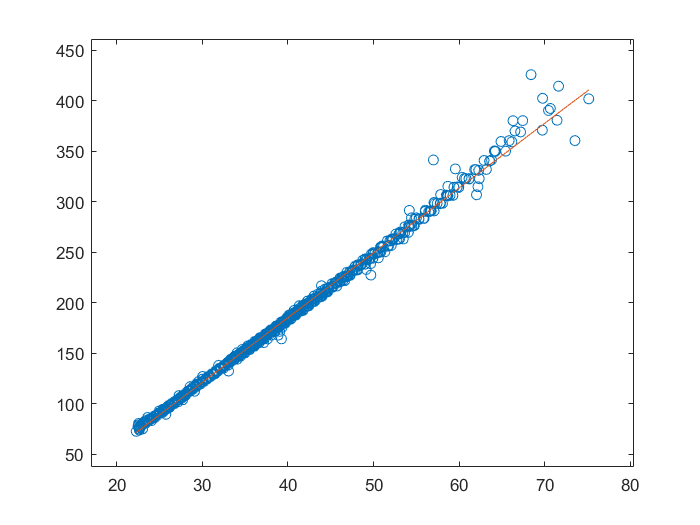

-- esfit ------------------------------------------------
Data size:                [42, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.00619e+01   edge 1.00000e-01   initial simplex
iteration   2: value 1.00424e+01   edge 5.40000e+00   expansion
iteration   3: value 9.95348e+00   edge 4.80000e+00   expansion
iteration   4: value 9.94590e+00   edge 5.40000e+00   reflection
iteration   5: value 9.64797e+00   edge 6.30000e+00   expansion
iteration   6: value 9.64797e+00   edge 6.30000e+00   reflection
iteration   7: value 5.86971e+00   edge 9.90000e+00   expansion
iteration   8: value 2.28800e-01   edge 9.90000e+00   reflection
iteration   9: value 2.28800e-01   edge 5.40000e+00   reflection
iteration  10: value

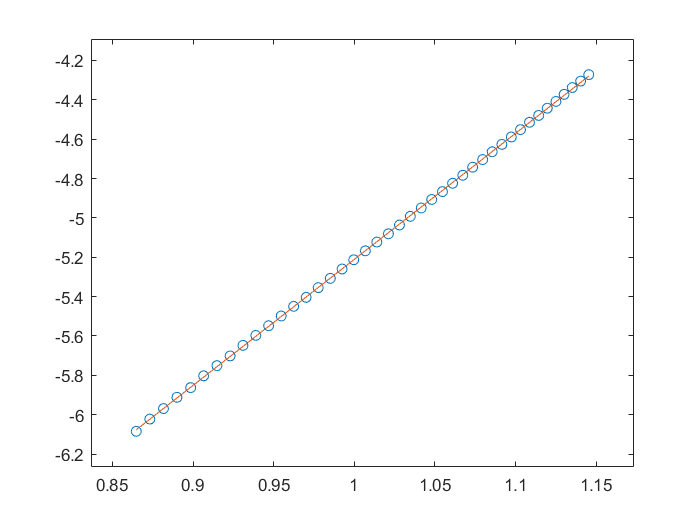

    Rs_ = -Fit1{ii}.pfit(2)/Fit1{ii}.pfit(1);
    Vc = V(idxStart:end) - I(idxStart:end)*Rs_; % Corrected voltage values
    lnI = log(I(idxStart:end));

    p0 = [18.8, -6]; vary = [18, 8];
    Fit2{ii} = esfit(lnI,@(p) linModel(Vc, p), p0, vary);
    
    xDummy = linspace(min(Vc), max(Vc), 1000);
    figure()
    plot(Vc, lnI, 'o')
    hold on
    plot(xDummy, Fit2{ii}.scale*Fit2{ii}.pfit(1)*xDummy + Fit2{ii}.scale*Fit2{ii}.pfit(2))
    xlim(setAxLim(Vc, 0.1))
    ylim(setAxLim(lnI, 0.1))
end

for ii = 1:nStart
    Fit1_ = Fit1{ii};
    S = Fit1_.scale;
    alpha1(ii) = S*Fit1_.pfit(1);
    alpha1Std(ii) = S*Fit1_.pstd(1);
    Rs(ii) = -S*Fit1_.pfit(2)/alpha1(ii);


$$d\;R_S =d\;\left(\frac{p_2 }{\alpha \;}\right)=\frac{d\;p_{2\;} }{\alpha \;}+\frac{p_2 }{\alpha^2 }d\alpha =R_S \left(\frac{{d\;p}_2 }{p_2 }+\frac{d\alpha }{\alpha \;}\right)$$


    RsStd(ii) = Rs(ii)*(Fit1_.pstd(2)/Fit1_.pfit(2) + alpha1Std(ii)/alpha1(ii));

    Fit2_ = Fit2{ii};
    S = Fit2_.scale;
    alpha11(ii) = S*Fit2_.pfit(1);    % Another value of alpha
    alpha11Std(ii) = S*Fit2_.pstd(1);
    Is1(ii) = exp(S*Fit2_.pfit(2));


$$d\;I_S \;=d\;\left(\exp \left(p_2 \right)\right)=\exp \left(p_2 \right)*d\;p_2 =I_S *{d\;p}_2$$


    Is1Std(ii) = Is1(ii)*S*Fit2_.pstd(2);
end

Index exceeds the number of array elements. Index must not
exceed 1.

Out = struct('alpha1', alpha1, ...
    'alpha1Std', alpha1Std, ...
    'alpha11', alpha11, ...
    'alpha11Std', alpha11Std, ...
    'Rs', Rs, ...
    'RsStd', RsStd, ...
    'Is1', Is1, ...
    'Is1Std', Is1Std);

Rs

Is1

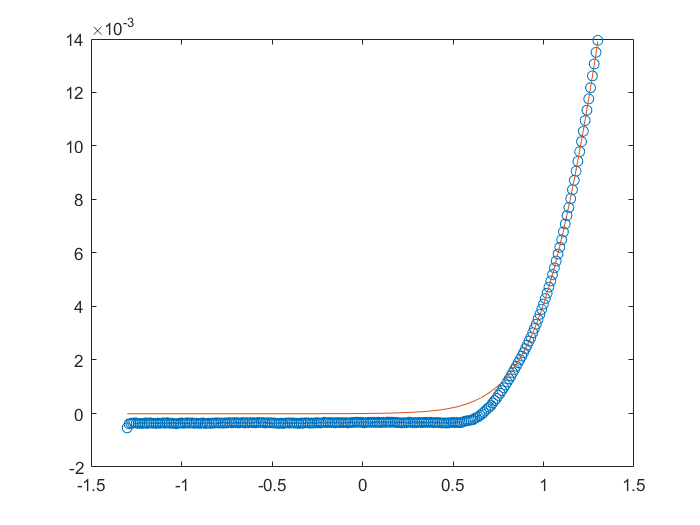

figure()
plot(V, I, 'o')
hold on
plot(V, onediodemodel(V, I, [Is1(1), Rs(1), 1e30, alpha1(1)]))

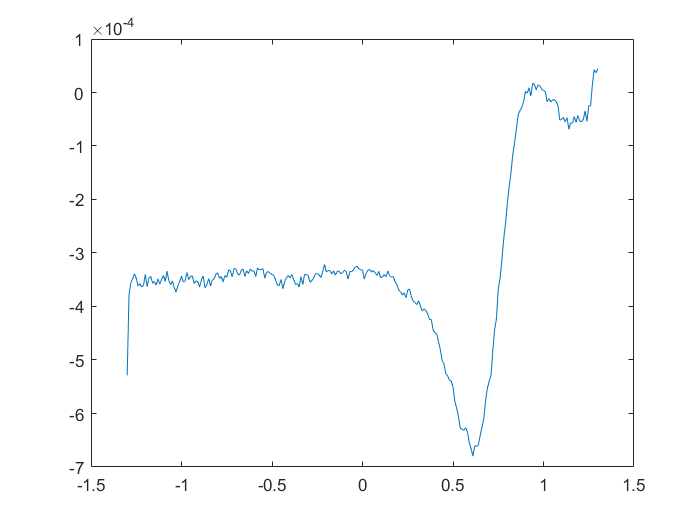

figure()
plot(V, I - onediodemodel(V, I, [Is1(1), Rs(1), 1e30, alpha1(1)]))

iSTART = 5;
Vc = V - I*Rs(iSTART);
I1 = Is1(iSTART)*exp(alpha1(iSTART)*Vc);

Measurement error: take out spike

Vrange = [-1.4 -1 -0.55 1.5];
idxCut = (V > Vrange(1) & V < Vrange(2)) | (V > Vrange(3) & V < Vrange(4));
Vcut = V(idxCut);
Vccut = Vc(idxCut);
Icut = I(idxCut);

stop = 28;
figure()
plot(V(1:50), I(1:50))
hold on
plot(Vcut(1:stop), Icut(1:stop), 'o')
I_ = Icut - I1(idxCut);
I_ = I_(1:stop);
V_ = Vcut(1:stop);
Vc_ = Vccut(1:stop);
figure()
plot(V_, I_, 'o')
alpha20 = alpha1(iSTART)
n20 = 1/(alpha20*0.02585)
prova = @(a) 5.e-6*(exp(a*Vc_) - 1) + Vc_/2.5e5;
OptFit = optimset('display', 'off');
alpha2 = lsqnonlin(@(p) 10e10*(I_ - ILowVoltage(I_, Vc_, p)), alpha20)
n2 = 1/(alpha2*0.02585)
[IfitLow, param2] = ILowVoltage(I_, Vc_, alpha2);
Is2 = param2(1)
Rsh = 1/param2(2)
figure(); plot(V_, I_, 'o')
hold on; plot(V_, IfitLow, 'o')

Rshinv = Vc_ \ I_;
Rsh = 1/Rshinv
Rshinv = V_ \ I_;
Rsh = 1/Rshinv

function [Ifit, C] = ILowVoltage(I, Vc, alpha2)
    I_ = exp(alpha2*Vc) - 1;
    X = [I_ Vc];
    C = X \ I;      % C(1) = Is2, C(2) = 1/Rsh
    Ifit = X * C;
end
function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end
function Ifit = twodiodemodel(V, I, p)
    % p = [I01, Rs, Rsh, alpha1, I02, alpha2]
    Idiode1 = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Idiode2 = p(5)*(exp(p(6)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode1 + Idiode2 + Ish;
end